##  Create Rasters Aligned to Syllable onsets

****SKIP if spiketimes file has already been generated. ****

Find all trials of a given syllable (or sequence) and create array of spikes during a window containing syllable pre-onset (set below), spike/sequence, and postmotor cushion spiketimes (hard coded to 0.1 s).

syl_seq = 'r'; 
birdname = 'br177yw112';
day = 68;
neuron_name = [birdname '_day' num2str(day)];
ch = 9; 
premotor_win = 0.2; %sec
filestoplot = 'ch9_passed_files.txt';
[clean_trials_table_b] = get_motif_spikes_from_list(neuron_name,syl_seq,ch,premotor_win,filestoplot);

Done. There are 452 clean trials and 0 trials with artifact.
Elapsed time is 4.201338 seconds.


Plot a sample spectrogram with rasters aligned to syllable onset

day = 68

Plotting data without time warping...


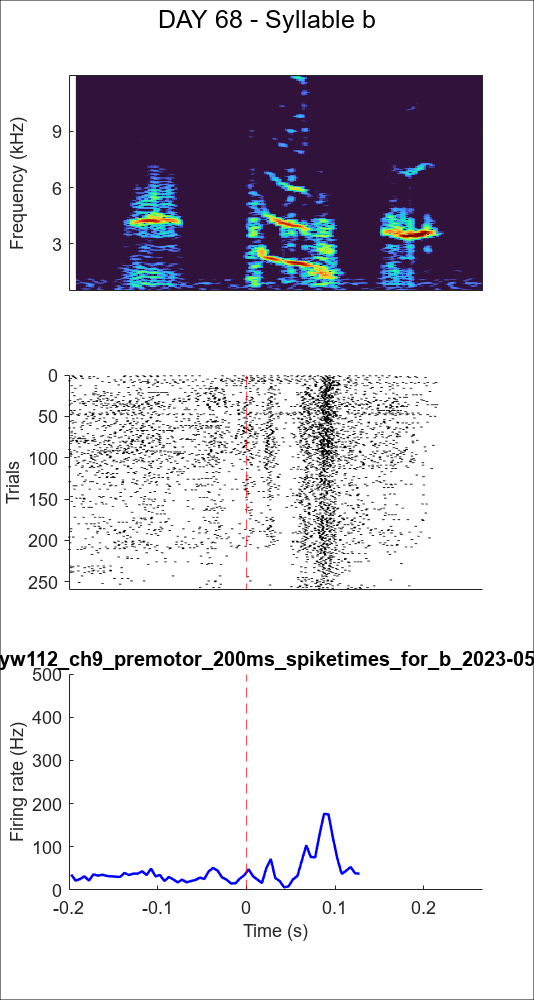

Plotting data without time warping...


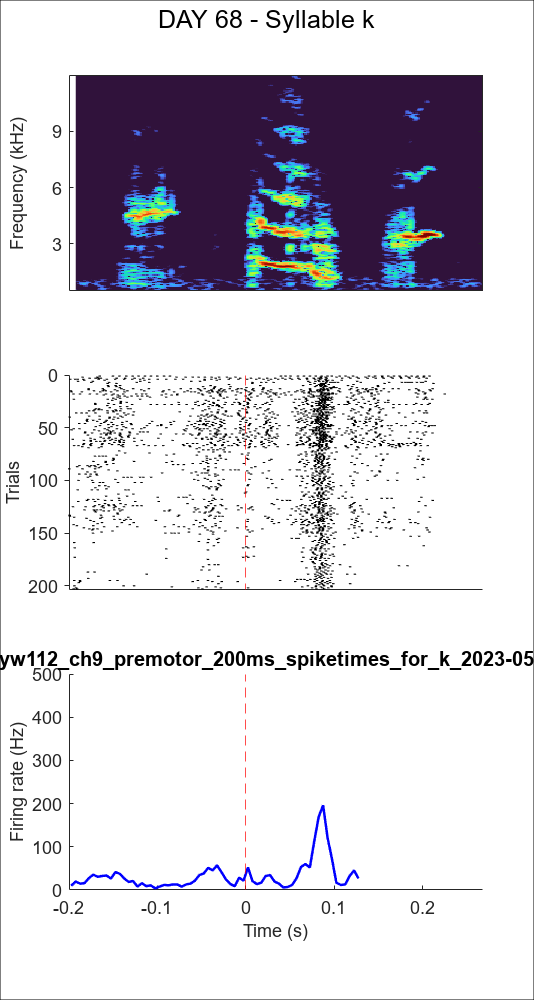

Plotting data without time warping...


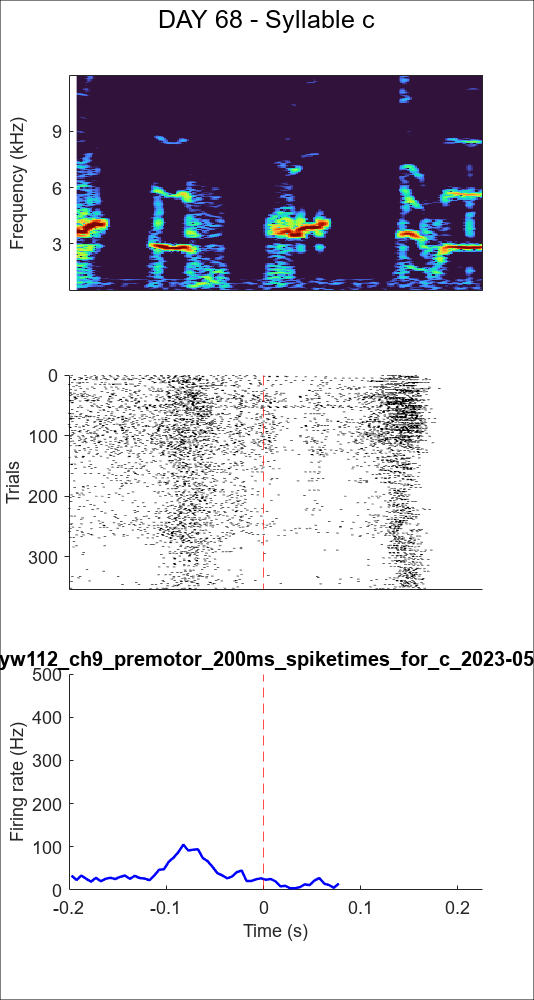

Plotting data without time warping...


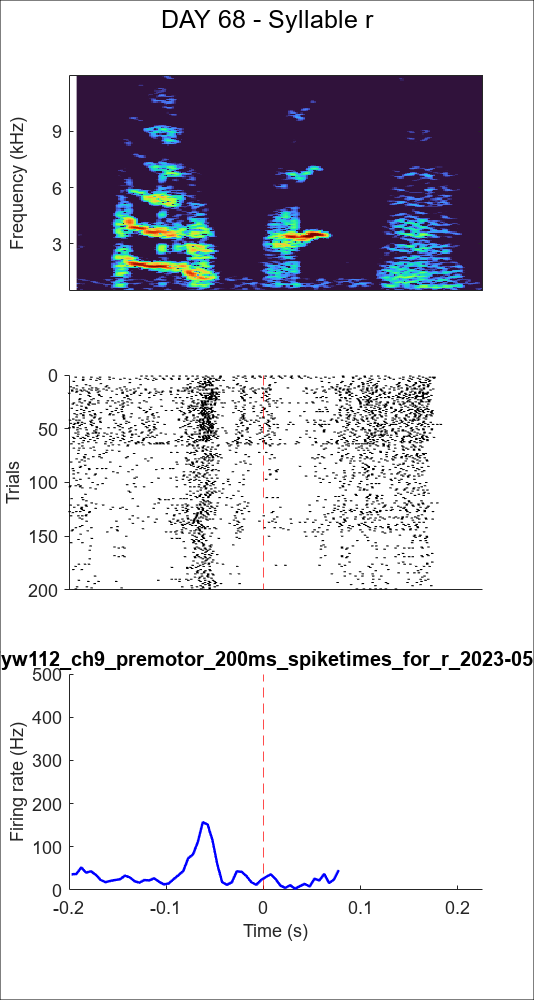

day = 73

Plotting data without time warping...


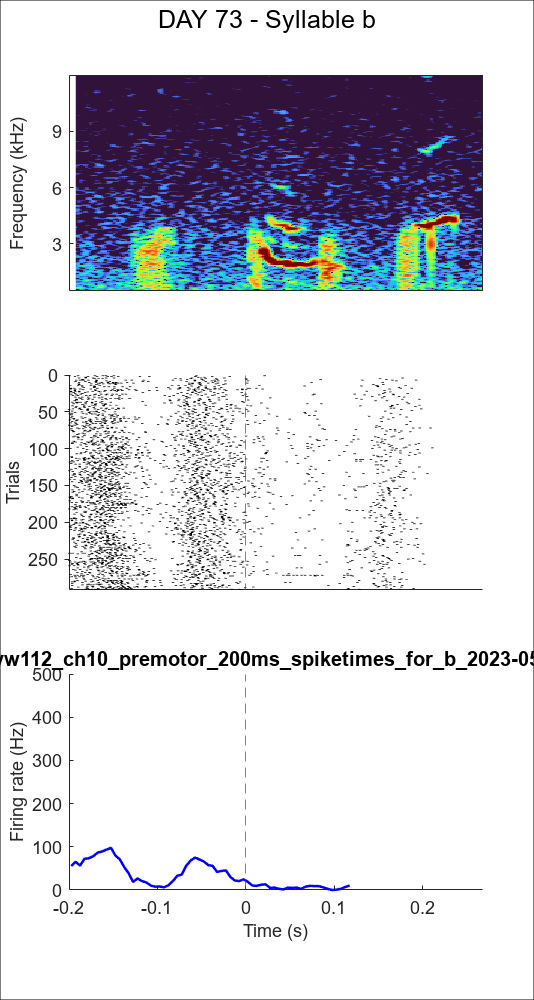

Plotting data without time warping...


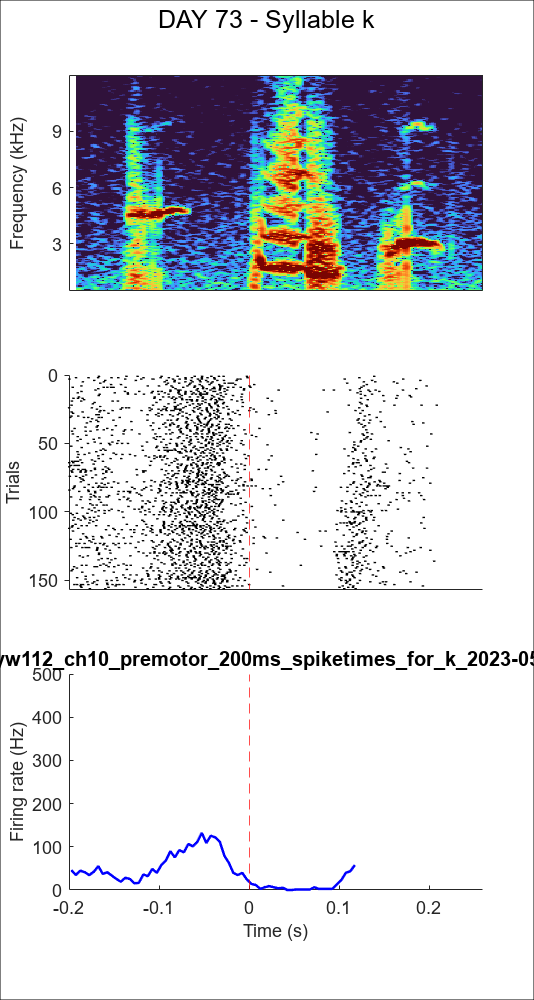

Plotting data without time warping...


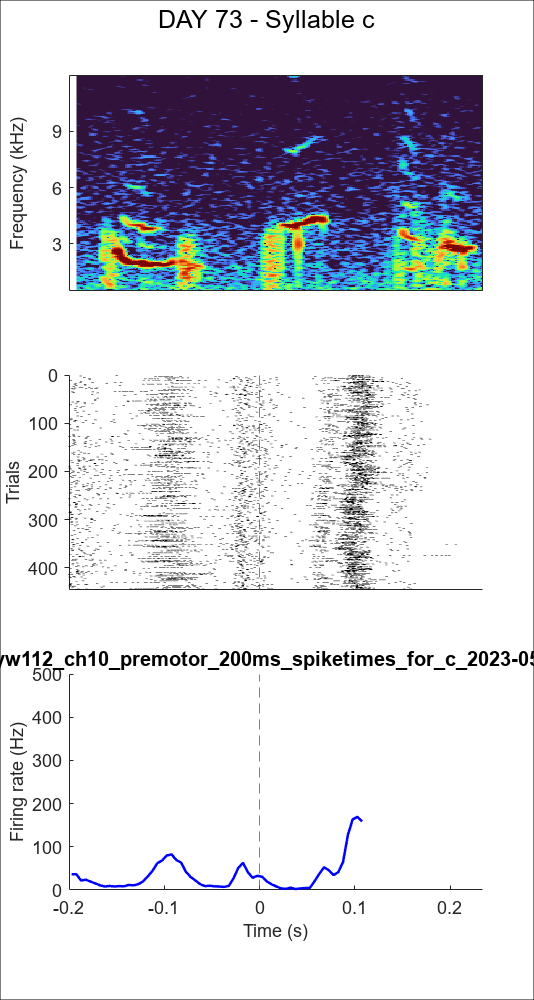

Plotting data without time warping...


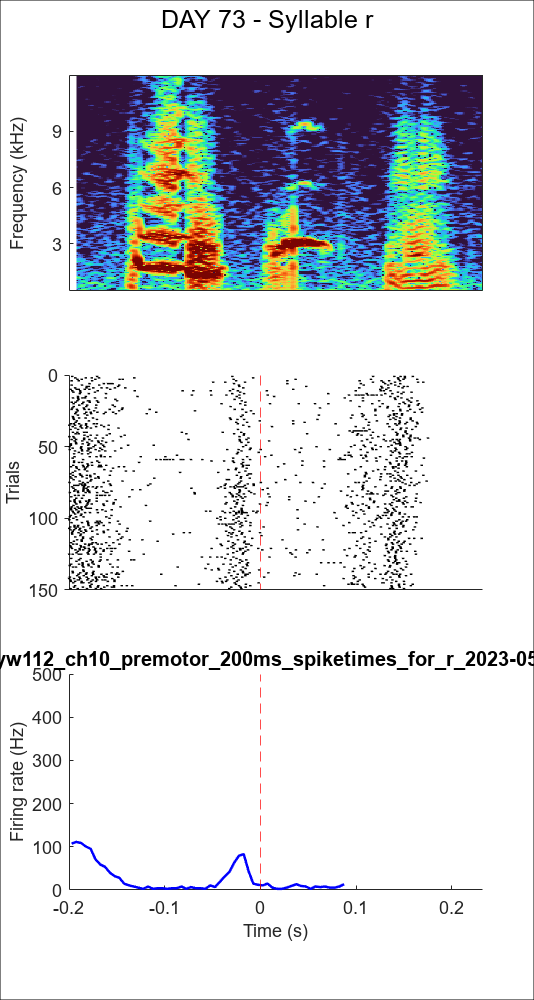

day = 88

Plotting data without time warping...


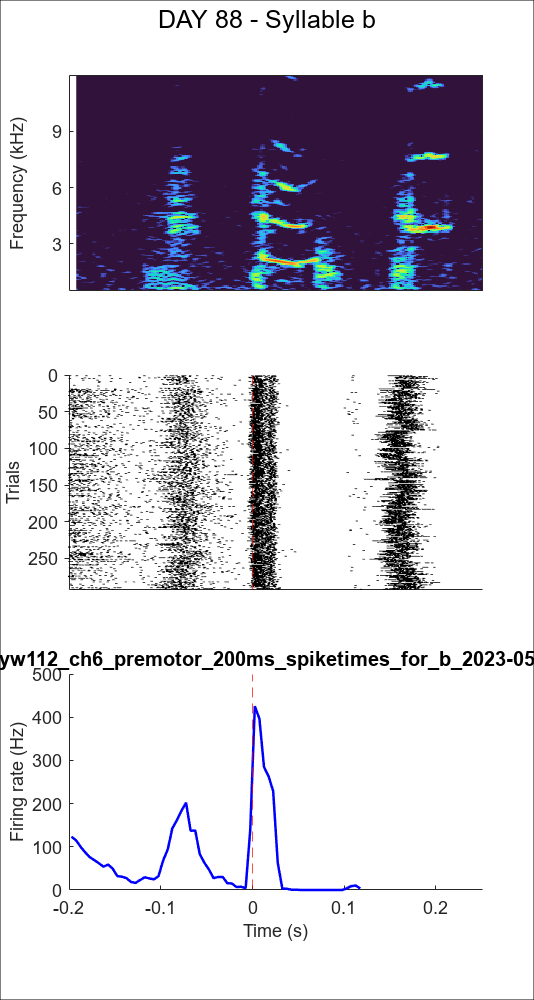

Plotting data without time warping...


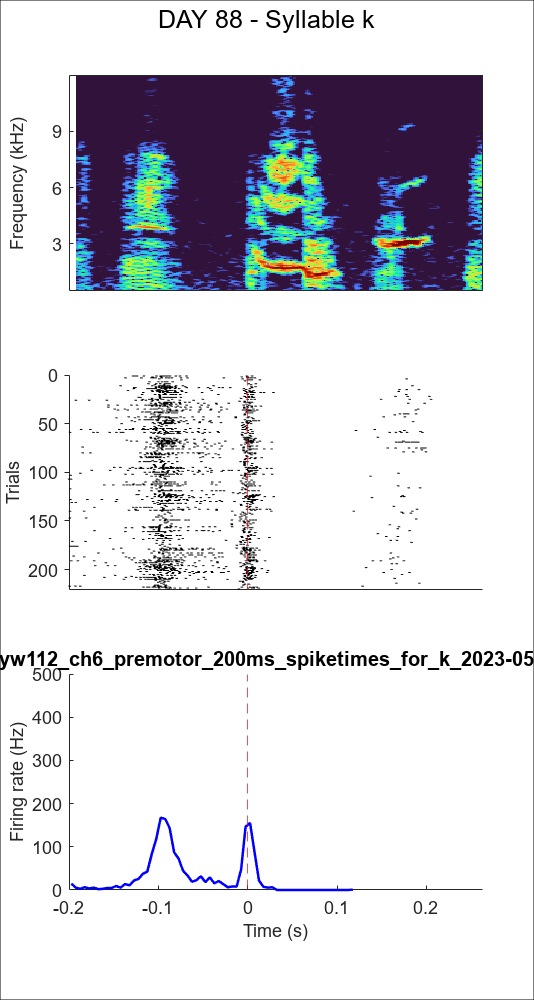

Plotting data without time warping...


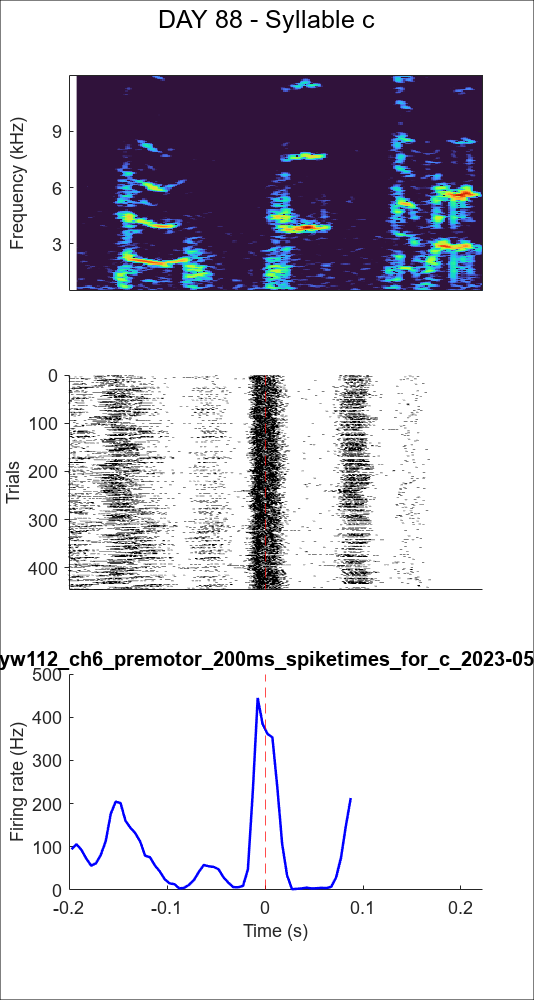

Plotting data without time warping...


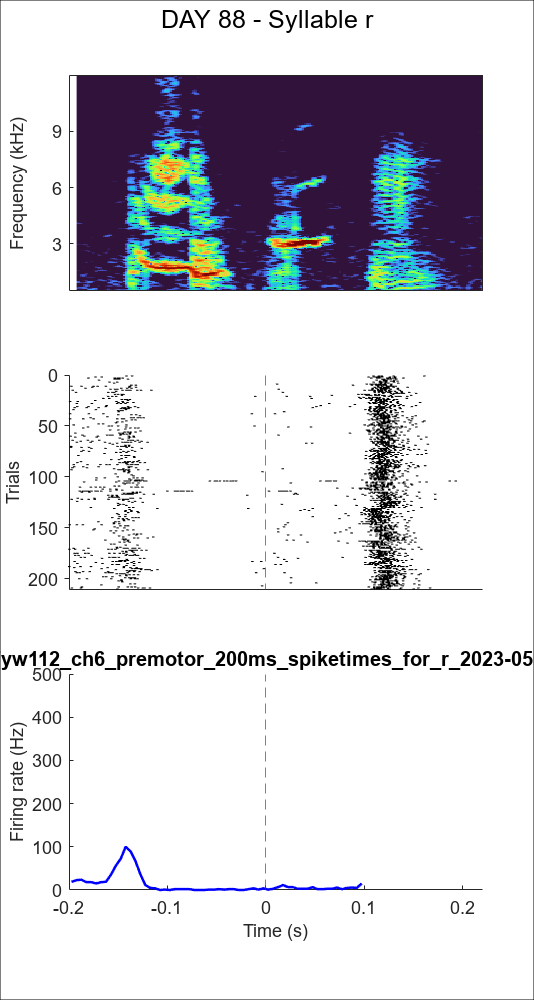

syls = ['b' 'k' 'c' 'r']; 
days = [68 73 88];
date = '2023-05-06'; % date that the spike-syl file was created
premotor = 200; %premotor window in ms

% Choose the spectrogram file for the corresponding day
for d = 1:length(days)
    day = days(d);
    switch day
        case 68
            song_file = 'br177yw112_221203_120855_songbout6.mat'; 
            ch = 9;
        case 73
            song_file = 'br177yw112_221208_112140_songbout3.mat';
            ch = 10;
        case 88
            song_file = 'br177yw112_221223_130500_songbout1.mat';
            ch = 6;
    end
    
    for s = 1:length(syls)
        syl = syls(s);
        eval(sprintf("motif_sumfile = '%s_ch%d_premotor_%dms_spiketimes_for_%s_%s.mat';", birdname,ch,premotor,syl,date));
        plot_multiple_FRs(song_file, motif_sumfile,align_syl_num_all)
        title = ['DAY ' num2str(day) ' - Syllable ' syl];
        textbox1 = annotation('textbox',[0 0 1 1],'String', title,...
        'fontsize',15,'HorizontalAlignment','center','VerticalAlignment','cap');
    end
end